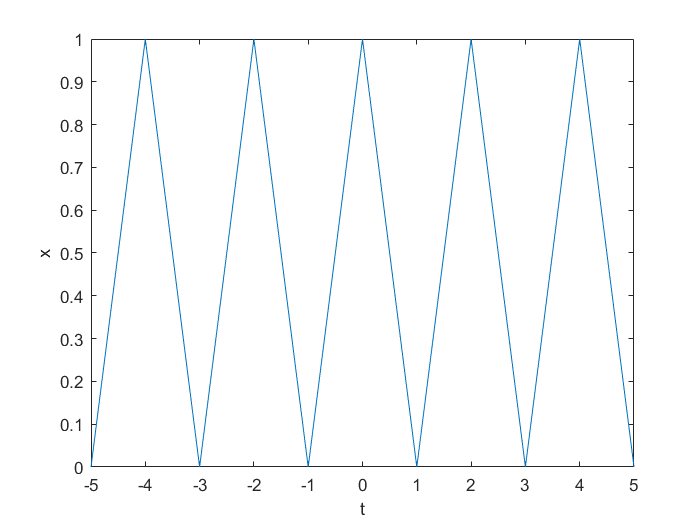

clc
close all
m=5;
t=-m:1:m;
x=zeros(size(t));
y=zeros(size(t));
t1=t-2;
x(t<=-1 & t>1)=0;
x(t>-1 & t<=0)=1 +t(t>-1 & t<=0);
x(t>0 & t<=1)=1-t(t>0 & t<=1);
for i= -2:2
y(t > -1 +(2*i) & t <=0 + (2*i)) = 1 + t(t <= 0 & t > -1);
y(t > 0 +(2*i) & t <= 1 + (2*i) ) = 1 - t(t > 0 & t <= 1);
y(t>1 & t<-1) = 0;
end
plot(t,y)
xlabel('t');
ylabel('x');